clear
clc
close all

%% Change directory
% Get the full path of the currently running script
if isdeployed
    % If the code is deployed, use the built-in method
    scriptFullPath = mfilename('fullpath');
else
    % If running in the MATLAB environment, use the editor API
    scriptFullPath = matlab.desktop.editor.getActiveFilename;
end

% Extract the directory part of the path
[scriptDir, ~, ~] = fileparts(scriptFullPath);

% Change the current directory to the script's directory
cd(scriptDir);

% Display the current directory to confirm the change
disp(['Current directory changed to: ', scriptDir]);

Current directory changed to: C:\Users\giaco\Git_Repositories\Semester_Thesis_1\Data\Battery


% Voltage vs SoC
data = readtable('Data/Battery/standard_battery.csv');
SoC = data.Var1;
voltage = data.Var2;

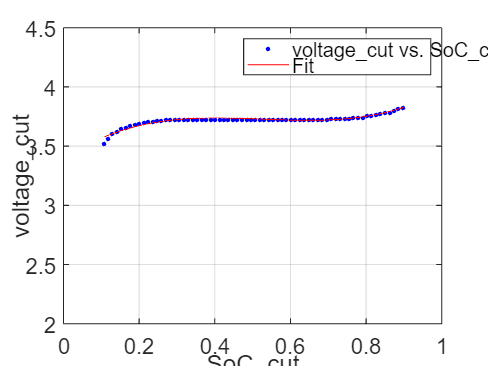

% From image of internet
SoC_min = 0.1;
mask = SoC >= SoC_min & SoC <= 0.9;
SoC_cut = SoC(mask);
voltage_cut = voltage(mask);

[fitresult_cut, ~] = safeFit(SoC_cut, voltage_cut);


coefficients = coeffvalues(fitresult_cut);
disp('Fitted Coefficients of cut SoC');

Fitted Coefficients of cut SoC


disp(formula(fitresult_cut));

p1*x^3 + p2*x^2 + p3*x + p4


disp(coefficients);

    2.7861   -4.3848    2.1768    3.3904



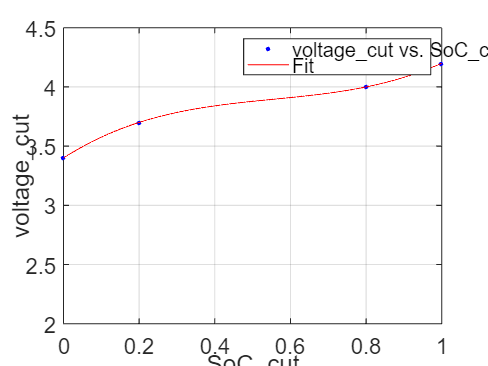


% From 4 good points
x_soc = [0, 0.2, 0.8, 1];
y_voltage = [3.4, 3.7, 4, 4.2];

[fitresult_4points, ~] = safeFit(x_soc, y_voltage);


coefficients = coeffvalues(fitresult_4points);
disp('Fitted Coefficients of 4 points');

Fitted Coefficients of 4 points


disp(formula(fitresult_4points));

p1*x^3 + p2*x^2 + p3*x + p4


disp(coefficients);

    1.8750   -3.1250    2.0500    3.4000



saving = 0;
if saving == 1
    headers = {'a3', 'a2', 'a1', 'a0'};
    coeff_table = array2table(coefficients, 'VariableNames', headers);
    filename = 'battery_fitted_coefficients_3rd.csv'; % Change to .xlsx for Excel file
    writetable(coeff_table, filename);
end

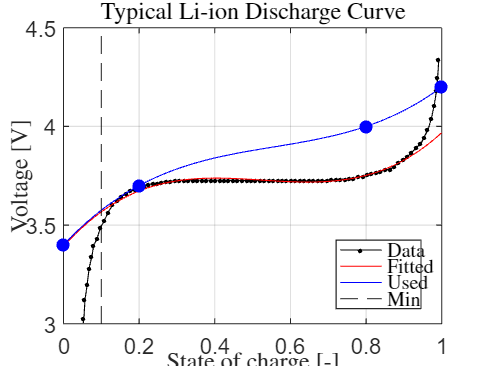

x = linspace(0,1,100);

figure
hold on
grid on
box on
plot(SoC, voltage, '.-k', 'DisplayName', 'Data')
plot(x, fitresult_cut(x), 'r-', 'DisplayName', 'Fitted');
plot(x, fitresult_4points(x), 'b-', 'DisplayName', 'Used');
scatter(x_soc, y_voltage, 'b', 'filled','HandleVisibility', 'off');
xline(SoC_min, '--k', 'DisplayName', 'Min');
xlim([0 1])
ylim([3 4.5])
xlabel('State of charge [-]', 'Interpreter', 'latex')
ylabel('Voltage [V]', 'Interpreter', 'latex')
title('Typical Li-ion Discharge Curve', 'Interpreter', 'latex')
legend('Location','best', 'Interpreter', 'latex')